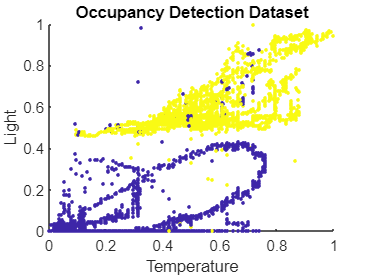

rng('default');  % Random seed for reproducibility

% Load Occupancy Detection Dataset
opts = detectImportOptions('datatraining.txt',"VariableNamingRule","preserve");
% Feature selection
opts.SelectedVariableNames = {'Var3', 'Var5','Var8'};
data = readtable('datatraining.txt',opts);
data = rmmissing(data);

% Convertion from table to array matrix
X1 = table2array(data(:,1));
X2 = table2array(data(:,2));
Y = table2array(data(:,3));

for i = 1:length(Y)
    if Y(i)==0
        Y(i)=-1;
    end
end

% Removing outliers
X1 = X1(X2<900);
X2 = X2(X2<900);
Y = Y(X2<900);

% Normalizing the features
X1 = (X1 - min(X1)) / (max(X1)-min(X1));
X2 = (X2 - min(X2)) / (max(X2)-min(X2));

% Plot of the dataset
figure
scatter(X1,X2,5,Y,'filled');
title('Occupancy Detection Dataset');
xlabel('Temperature');
ylabel('Light');

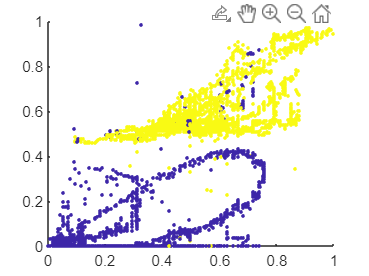



n = length(Y); % numero di punti  
p = 0.02; % frazione di punti etichettati

% sample generator with gaussian distribution
l = ceil(n*p); % numero di sample etichettati (occhio fallo intero)
samp=randperm(n,l);
indices=1:n;
X = [X1,X2];
y_tot = Y;
u=n-l;

% build the data
X_samp=X(samp,:);
X_unlabeld = X(setdiff(1:end,samp),:);
y_samp=y_tot(samp);
y_exact=y_tot(setdiff(1:end,samp));

%visualize the data
scatter(X(:,1),X(:,2),5,y_tot,'filled')

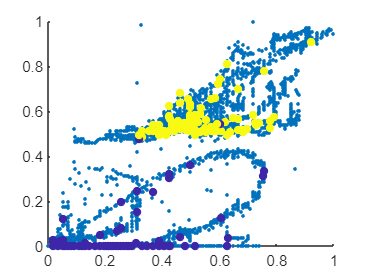

figure;
scatter(X(:,1),X(:,2),5,'filled')
hold on 
scatter(X_samp(:,1),X_samp(:,2),25,y_samp,'filled')
hold off


%Calcolo distanze "utili", lab-nolab e nolab-lab
D_samp=zeros(l,u);
for i=1:l
    for j=1:u
        D_samp(i,j)=norm(X_samp(i,:)-X_unlabeld(j,:));
    end
end

D=zeros(u,u);
for i=1:u
    for j=1:u
        D(i,j)=norm(X_unlabeld(i,:)-X_unlabeld(j,:));
        D(j,i)=D(i,j);
    end
end

% Calcolo pesi exp(-x)
W_samp= exp(-D_samp.^2/2);
W = exp(-D.^2/2);


% Calcolo L, lipschitz constant

% lambda_min = min(eig(W));
lambda_max = max(eig(W));
W_l = zeros([1,u]);
W_u = zeros([1,u]);

for i=1:u
    W_l = sum(W_samp(:,i));
    W_u = sum(W(:,i));
end
%L = max(W_l+W_u)-lambda_min questa in realtà funziona ugualmente
L=sqrt(max(W_l+W_u)^2+lambda_max^2);




%Parameters for the gradient methods
y0 = -1 + 2.*rand(u,1); %cioè delle etichette casuali per i dati no-lab 
eps = 1e-4; %tolleranza
maxit = 1000; %iterazioni max
%Choose the method to be tested
metodo="GD";  %BCGDcyc con armijo (2) è stralento
step_size=input('Choose step size:'); % regola per lo step_size
alpha=1/L;   % per lo step_size fisso
delta=0.5;   % per l'armijo rule

switch metodo
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%METODO DEL GRADIENTE CLASSICO
    case "GD"
[y, timeVec, Norms, accuracy]= ...
    GD_fixed(alpha,maxit,eps,y0,y_samp,W,W_samp,step_size,y_exact,delta); 


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% BCGD with cyclic rule
    case "BCGDcyc"
[y, timeVec, Norms, accuracy] = ...
    BCGD_cyclic(alpha,y0,maxit,eps,y_samp,W,W_samp,step_size,y_exact,delta);

   
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% BCGD with randomized rule
    case "BCGDrand"
[y, timeVec, Norms, accuracy] = BCGD_random(alpha,maxit,eps,y0,y_samp,W,W_samp,step_size,y_exact,delta);

end


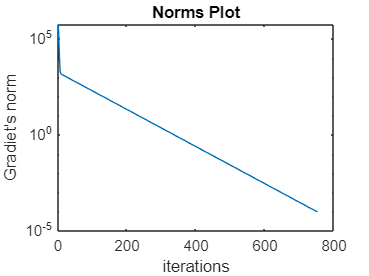


%PLOT THE RESULTS
figure(1)
semilogy(Norms)
title('Norms Plot')
xlabel('iterations')
ylabel("Gradiet's norm")

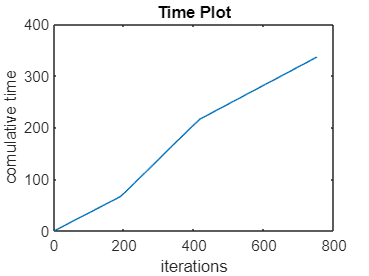

figure(2)
plot(timeVec)
title('Time Plot')
xlabel('iterations')
ylabel('comulative time')

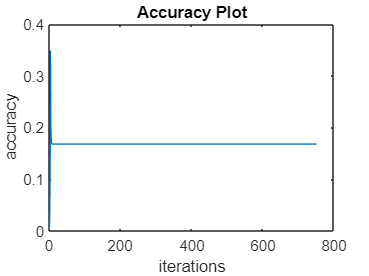

figure(3)
plot(accuracy)
title('Accuracy Plot')
xlabel('iterations')
ylabel('accuracy')

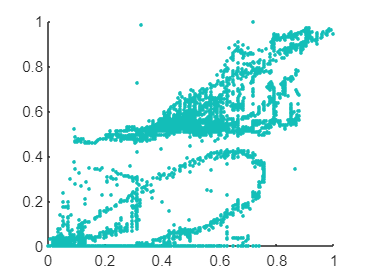

y = sign(y);
scatter(X_unlabeld(:,1),X_unlabeld(:,2),5,y,'filled')